# Interface para o método de Euler

CHAMADA DE FUNÇÕES:

    MEuler

    MeulerMelhorado

    dsolve

26/03/2021  Arménio Correia  armenioc@isec.pt

Trabalho realizado por:(23/04/2021)

        Diogo Silva - 2020138438 - a2020138438@isec.pt

        Hugo Ferreira - 2020128305 - 2020128305@isec.pt

        Rúben Mendes  - 2020138473 - a2020138473@isec.pt

clc
clear

syms y(t)

strF = input('f(t,y) = ','s');
f = @(t,y)eval(vectorize(strF));
disp('----- Método de Euler e Euler Melhorado ------ ');

----- Método de Euler e Euler Melhorado ------ 


a  = str2num(input('a = ','s'));
b  = str2num(input('b = ','s'));
n  = str2num(input('n = ','s'));
y0 = str2num(input('y0 = ','s'));
tic
yEuler = MEuler(f,a,b,n,y0)

yEuler =     6.0000   10.8000   22.8960   55.8662  154.1908  474.9077


toc

Elapsed time is 0.020377 seconds.


tic
yEulerM = MeulerMelhorado(f,a,b,n,y0)

yEulerM =     6.0000   10.8000   22.8960   55.8662  154.1908  474.9077


toc

Elapsed time is 0.016906 seconds.



sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = 6\,{\mathrm{e}}^{t^{2}}\,{\mathrm{e}}^{-1}$$

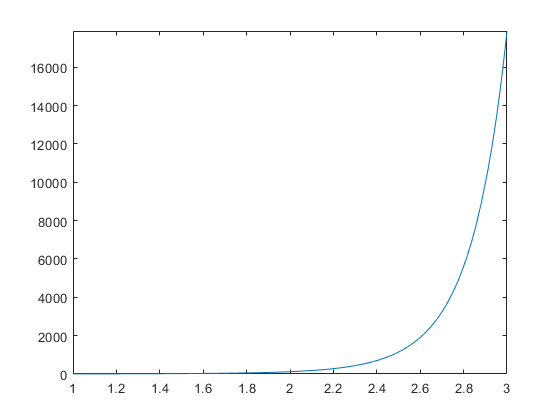

fplot(sExata,[a,b])


g =@(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroEuler = abs(yExata-yEuler);
erroEulerM = abs(yExata-yEulerM);
disp('----- Tabela de Valores ------ ');

----- Tabela de Valores ------ 


tabela = [t.',yExata.',yEuler.',yEulerM.',erroEuler.',erroEulerM.'];
array2table(tabela,"VariableNames",{'t','Exata','Euler','Euler Melhorado','Erro Euler','Erro Euler Melhorado'})

ans = 6×6 table
     t     Exata     Euler     Euler Melhorado    Erro Euler    Erro Euler Melhorado
    ___    ______    ______    _______________    __________    ____________________

      1         6         6             6         1.7764e-15         1.7764e-15     
    1.4     15.67      10.8          10.8             4.8702             4.8702     
    1.8     56.36    22.896        22.896             33.464             33.464     
    2.2    279.15    55.866        55.866             223.29             223.29     
    2.6    1904.1    154.19        154.19             1749.9             1749.9     
      3     17886    474.91        474.91              17411              17411     



disp('----- Gráfico de Soluções ------ ');

----- Gráfico de Soluções ------ 


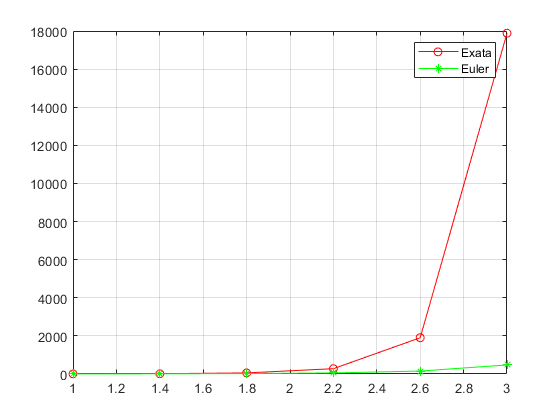

plot(t,yExata,"-ro")
hold on
plot(t,yEuler,"-g*")
hold off
grid on
legend('Exata','Euler')

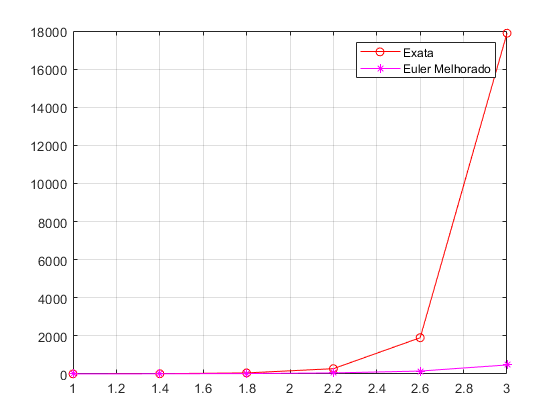



plot(t,yExata,"-ro")
hold on
plot(t,yEulerM,"-m*")
hold off
grid on
legend('Exata','Euler Melhorado')